# The Space Shuttle's Ballistic Trajectory

Instructions are in the task pane to the left. Complete and submit each task one at a time. 

This code loads and plots the altitude data. 

nasadata = readtable("./data/nasadata.csv");
timeFromNASA = nasadata.timeFromNASA;
heightFromNASA = nasadata.heightFromNASA;
[timeFromODE, heightFromODE] = ode45(@(t, y) 2*9.8*t, [0, 60], 0);

## Task 1

t = linspace(0, 60);

## Task 2

For the first 60 seconds, the shuttle accelerates almost constantly at 2*g*, where *g* is the acceleration due to gravity (*g* = 9.8).

a = 2*9.8;

## Task 3

Starting at rest with zero height, the height *h* of an object traveling straight up with a ballistic trajectory at constant acceleration *a* is given by the “*ballistic equation*”:

*h*(*t*)=1/2 *a**t^*2

h = 0.5 .* a .* t.^2;

## Task 4

plot(t, h, "k")
grid on

## Task 5

The ODE for the ballistic trajectory is

*d**h/d**t*=*a**t*

with *h*(*t*=0)=0.

This ODE has already been solved numerically for you with the results stored in the variables `heightFromODE` and `timeFromODE`.

hold on
plot(timeFromODE, heightFromODE, "ko")
hold off

## Task 6

NASA also collects data on the height of the shuttle as a function of time. This information has been provided in the Workspace as `timeFromNASA` and `heightFromNASA`.

hold on
plot(timeFromNASA, heightFromNASA, "r")
hold off

## Task 7

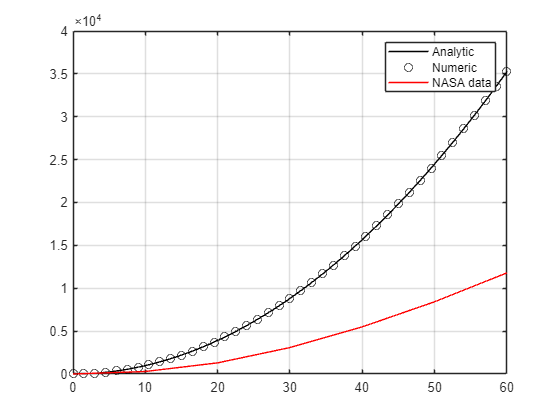

legend("Analytic", "Numeric", "NASA data")